# **CS/SE 4X03 Tutorial 1 - MATLAB Primer**

## Variables

### Variable Names

Variables are case-sensitive, alphanumeric combinations, with the first character being a letter. Underscores are allowed.

Ex: "x", "x1", "maxX", "max_distance" **but not** "1", "1x", "x!", "x/2"

Variables are assigned with the equal sign.

x = 10

x = 10

### Printing Variables to Terminal

In Matlab, if we do not put a semi-colon at the end of our line, it will also output the result:

x;
x

We can display the value of a variable using the `disp` command, or using printf style commands via `fprintf`

disp("x = " + x);
fprintf("x = %i\n",x);

x = 10

#### Brief Aside - `help`

You can use `help` to display information on a given MATLAB function.

help disp

 disp Display array.
    disp(X) displays array X without printing the array name or 
    additional description information such as the size and class name.
    In all other ways it's the same as leaving the semicolon off an
    expression except that nothing is shown for empty arrays.
 
    If X is a string or character array, the text is displayed.
 
    See also fprintf, sprintf, int2str, num2str, rats, format, details.

    Documentation for disp
    Other functions named disp



help fprintf

 fprintf Write formatted data to text file.
    fprintf(FID, FORMAT, A, ...) applies the FORMAT to all elements of array A and
    any additional array arguments in column order, and writes the data to a text
    file.  FID is an integer file identifier.  Obtain FID from FOPEN, or set it to 1
    (for standard output, the screen) or 2 (standard error). fprintf uses the
    encoding scheme specified in the call to FOPEN.
 
    fprintf(FORMAT, A, ...) formats data and displays the results on the screen.
 
    COUNT = fprintf(...) returns the number of bytes that fprintf writes.
 
    FORMAT is a character vector that describes the format of the output fields, and
    can include combinations of the following:
 
       * Conversion specifications, which include a % character, a
         conversion character (such as d, i, o, u, x, f, e, g, c, or s), and optional
         flags, width, and

Alternatively, MATLAB has excellent built in html documentation you can access in the topright corner or with the `doc` command.

doc fprintf

Within this documentation you can open live scripts to experiment with code, see the usage, and see similar/related MATLAB functions.

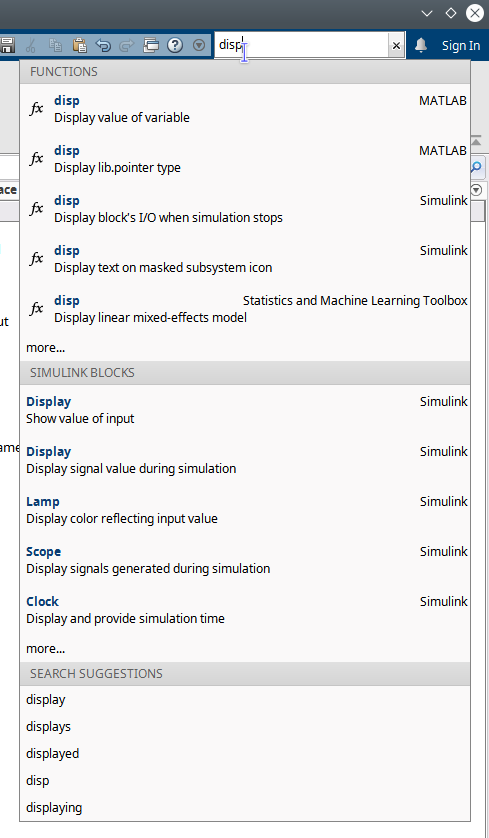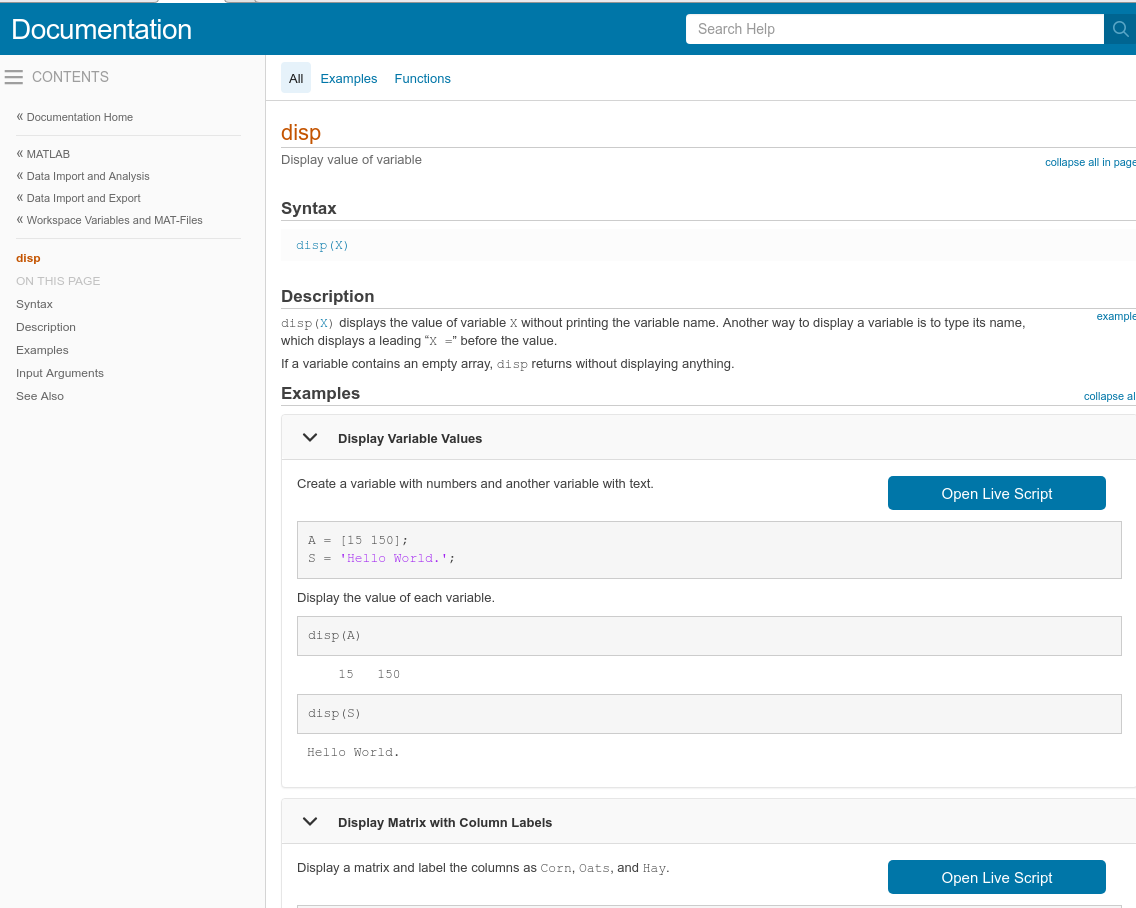

### Variables as Matrices

All variables are stored in the workspace as a matrix object. This allows intuitive representations of scalars (1x1 matrix), row vectors (Nx1 matrix), column vectors (1xN matrix) and matrices (NxM matrix)

We assign scalars simply with an equal sign.

xScalar = 10

xScalar = 10

We can create row vectors as a list of numbers between brackets.

A comma or space can be used to separate elements as you prefer.

xRowVector = [2,5,7,-3]

xRowVector =      2     5     7    -3


xRowVector2 = [2 5 7 -3]

xRowVector2 =      2     5     7    -3


Alternatively, we can use colons to create a row vector using the syntax `start:step:end`

yRowVector = 10:2:100

yRowVector =     10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40    42    44    46    48    50    52    54    56    58    60    62    64    66    68    70    72    74    76    78    80    82    84    86    88    90    92    94    96    98   100


The elements of a column vector are separated by semi-colons or a newline (Enter).

xColVector = [2;5;7;-3]

xColVector =      2
     5
     7
    -3


xColVector2 = [2
               5
               7
              -3]

xColVector2 =      2
     5
     7
    -3


Using the apostrophe (`'`) operator, we can get the transpose of a row vector generated with colons to get a column vector.

yColVector = (10:2:100)'

yColVector =     10
    12
    14
    16
    18
    20
    22
    24
    26
    28


We can combine these notations to create an NxM matrix

A = [1,2,3;4,5,6;7,8,9]

A =      1     2     3
     4     5     6
     7     8     9


A = [1:3
     4:6
     7:9]

A =      1     2     3
     4     5     6
     7     8     9


### Clearing Variables

Variables are stored in the workspace until cleared.

clear("x");

Alternatively, the entire workspace can be cleared with `clear` and the command window can be cleared with `clc`.

clear;
clc;

### Referencing Matrix Elements

We can reference an individual element of an object using parentheses.

v = [2,5,7,-3,0,1];
v(2)

ans = 5

We can also access a range of elements:

v(2:2:6)

ans =      5    -3     1


## MATLAB as a Column Major Language

A note worth stressing early with MATLAB is the way arrays are stored.

Many languages you are likely familiar with, such as C or Java start their arrays with an index of 0. In MATLAB the starting index is 1. This means a call such as `v(1)` will access the **first** element of v, not the second. This similarly means that a call of `v(0)` returns an error, as the indices are only defined starting with 1! If you are interfacing data between MATLAB and a language that starts its indices at 0, make sure you are accounting for this shift.

Another important distinction about MATLAB compared to other common languages is the way arrays are stored in memory and accessed by the CPU. MATLAB is referred to as a **column major **language. This is opposed to, for example C/C++, which is a **row major** language.

In a column major language, the entries of an array are stored contiguously via the columns and vice-versa in a row major language. This means that if you want to access elements from an array quickly, you must scan by the columns **not** the rows. A sort of pneumonic for this is that with respect to indices, row major languages goe in to out (i to j to k...) and column major languages go out to in (... to k to j to i).

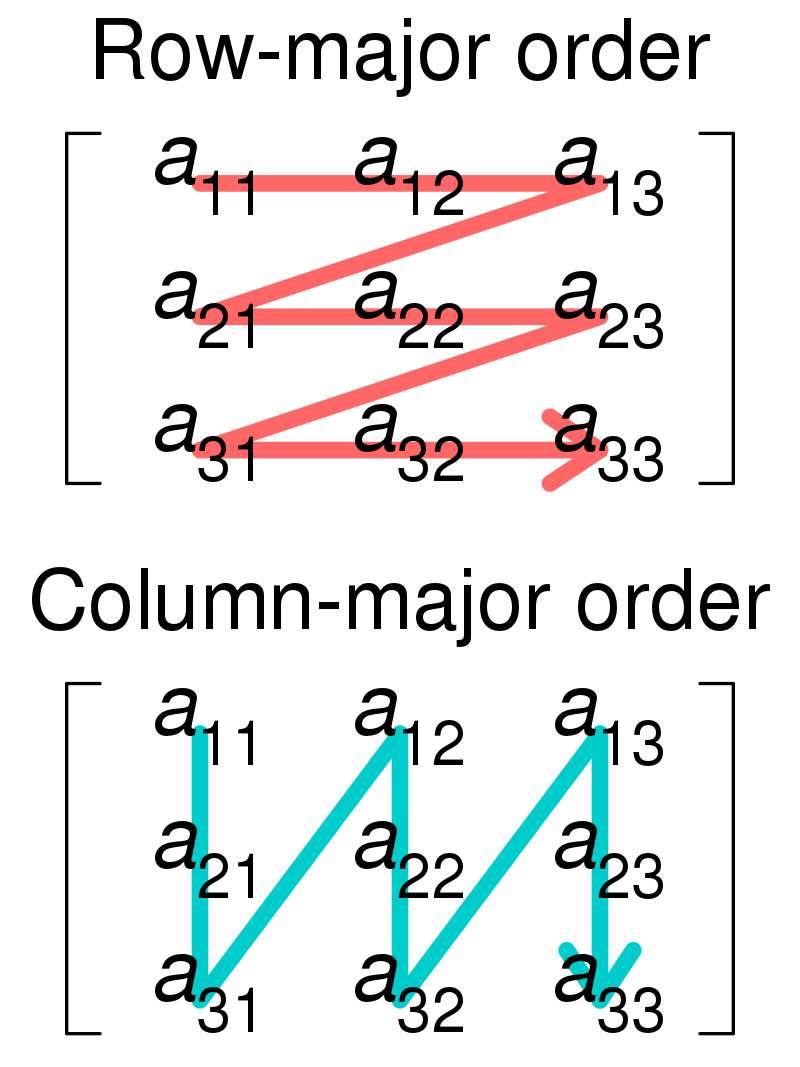

Consider the example:

clear
n = 5000;
A = zeros(n, n);
% Row major
tic;
for i = 1:n % slow loop
    for j = 1:n % fast loop
        A(i, j) = i + j;
    end
end
toc

Elapsed time is 0.665538 seconds.


% Column major assignment
tic;
for j = 1:n % fast loop
    for i = 1:n % slow loop
        A(i, j) = i + j;
    end
end
toc

Elapsed time is 0.137577 seconds.


Try to guess what the following will output before checking!

A = [1,2,3;4,5,6;7,8,9];
% To see the output, remove the semicolons and rerun the section
A(3,1);
A(2,:);
A(:,3);
A(7);

## Matrix Operators

MATLAB supports the basic mathematic operators (`+, -, *, /, ^`). 

Since the `*, /, ^` operators have different definitions for matrices and scalars, MATLAB notates element wise operation with a dot (`.*, ./, .^`).

By element-wise operation, the following is meant:

$A$ .$ \circ B =C \equiv c_{ij} = a_{ij}\circ b_{ij}$

Where $\circ$ is either:

- multiplication`  *`

- division`  / `or `\`(with direction indicating the denominator)

- exponentiation`  ^`

A = [1,2,3;4,5,6;7,8,9];
A + A

ans =      2     4     6
     8    10    12
    14    16    18


A - 2*A

ans =     -1    -2    -3
    -4    -5    -6
    -7    -8    -9


A * A

ans =     30    36    42
    66    81    96
   102   126   150


A

A =      1     2     3
     4     5     6
     7     8     9


A .* A

ans =      1     4     9
    16    25    36
    49    64    81


A ^ 2

ans =     30    36    42
    66    81    96
   102   126   150


A .^ A

ans =            1           4          27
         256        3125       46656
      823543    16777216   387420489


clear();

### Concept Check:

What do you think the following code will output?

xRowVector = [2,5,7,-3];
xColVector = [1/2;1/5;1/7;-1/3];
% Remove the semi-colons to see the result
% BUT before you do, try to think of what the output will be!
xRowVector * xColVector;
xColVector * xRowVector;
xRowVector .* xColVector;
xColVector .* xRowVector;
clear();

### Division

Division can occur left or right facing (`\, /`) and indicates matrix multiplication with the inverse of the direction it is facing.

A \ B = inv(A) * B

A / B =  A * inv(B)

Once again, a dot indicates element wise operation.

A .\ B = C, where $c_{ij} = \frac{b_{ij}}{a_{ij}}$

A ./ B = C, where $c_{ij} = \frac{a_{ij}}{b_{ij}}$

A = [1, 2; 3, 4];
B = [4, 2; -1, 3];
inv(A)*B

ans =    -9.0000   -1.0000
    6.5000    1.5000


A \ B

ans =    -9.0000   -1.0000
    6.5000    1.5000


A .\ B

ans =     4.0000    1.0000
   -0.3333    0.7500


A*inv(B)

ans =     0.3571    0.4286
    0.9286    0.7143


A / B

ans =     0.3571    0.4286
    0.9286    0.7143


A ./ B

ans =     0.2500    1.0000
   -3.0000    1.3333


**Note: MATLAB tells us that doing **`inv(B)*A`** can be slower and less accurate than **`A\B. `

**DO NOT USE **`inv`** FOR THIS PURPOSE. **

**USE \ or /**

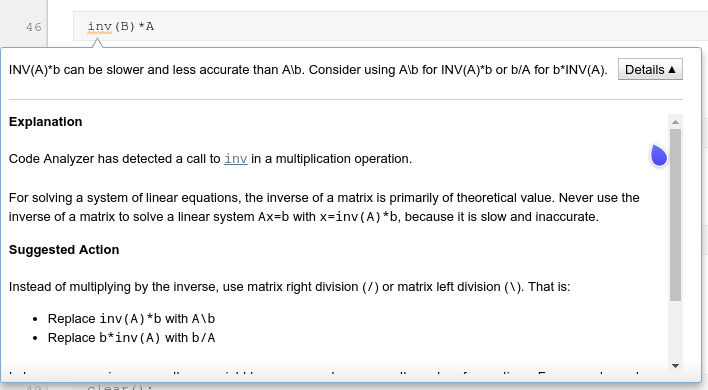

clear;

## Booleans

Booleans are represented in MATLAB as 1x1 matrices of either 0 (false) or 1 (true).

false

ans = logical
   0


true

ans = logical
   1


## Relational Operators

Relational operators in MATLAB:

less(greater) than `<(>)`

less(greater) than or equal to `<=(>=)`

equal to `==`

not equal to `~=`

1 < 1

ans = logical
   0


1 <= 1

ans = logical
   1


1 > 2

ans = logical
   0


2 >= 2

ans = logical
   1


## Logical Operators

Logical operators in MATLAB:

not `~`

or |

and `&`

~true

ans = logical
   0


~false

ans = logical
   1


true | false

ans = logical
   1


false | false

ans = logical
   0


true & false

ans = logical
   0


true & true

ans = logical
   1


## Plotting in MATLAB

Plotting in MATLAB is as simple as creating an array of data and inputing it into the plot function

help plot

 plot   Linear plot. 
    plot(X,Y) plots vector Y versus vector X. If X or Y is a matrix,
    then the vector is plotted versus the rows or columns of the matrix,
    whichever line up.  If X is a scalar and Y is a vector, disconnected
    line objects are created and plotted as discrete points vertically at
    X.
 
    plot(Y) plots the columns of Y versus their index.
    If Y is complex, plot(Y) is equivalent to plot(real(Y),imag(Y)).
    In all other uses of plot, the imaginary part is ignored.
 
    Various line types, plot symbols and colors may be obtained with
    plot(X,Y,S) where S is a character string made from one element
    from any or all the following 3 columns:
 
           b     blue          .     point              -     solid
           g     green         o     circle             :     dotted
           r     red           x     x-mark         

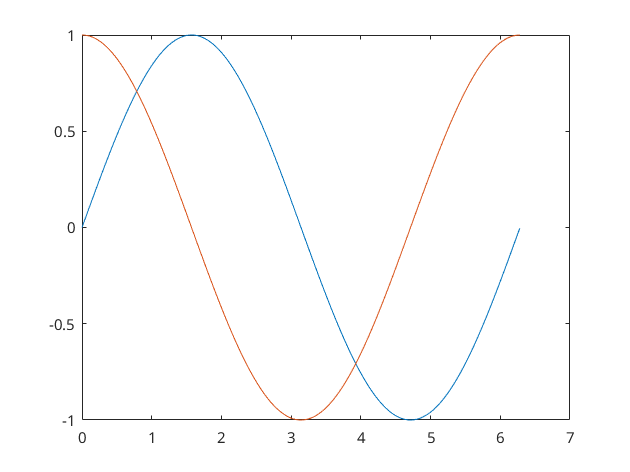

x = 0:0.01:2*pi;
y = sin(x);
z = cos(x);
plot(x,y,x,z);

### Configuring Plots

We can assign various specifications for our plots in a string format after the Y input.

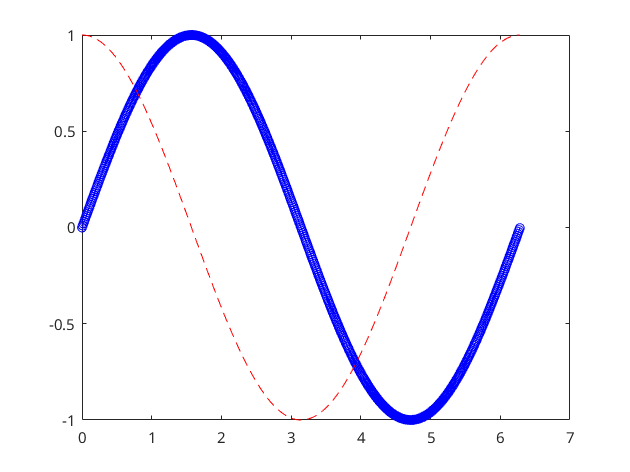

plot(x,y,"-ob",x,z,"--r")

This doesn't look very good. We can include additional settings to be applied to the entire plot by listing them as a string followed by the value after the data.

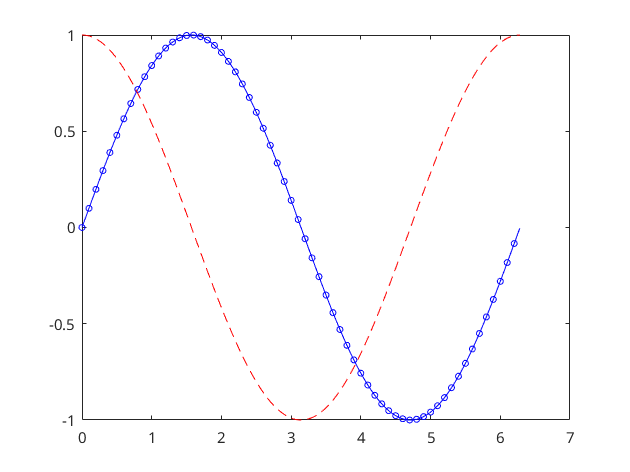

plot(x,y,"-ob",x,z,"--r",'LineWidth',0.1,'MarkerSize',4,"MarkerIndices",1:10:length(y))

### Dynamic Plotting

Various plot settings can be changed, even after we have plotted our data! This is a very handy feature of MATLAB that makes tweaking settings very easy!

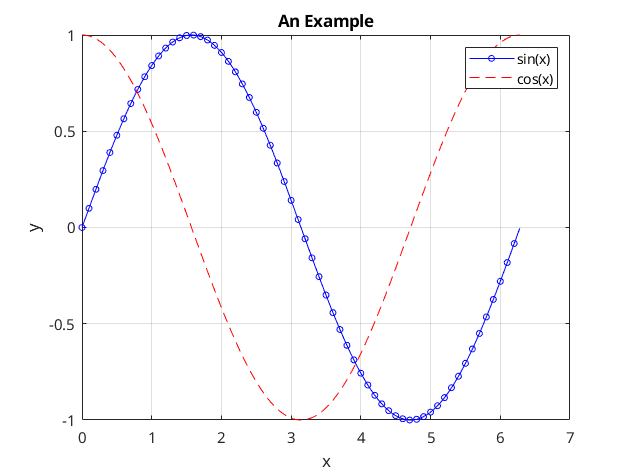

xlabel 'x';
ylabel 'y';
title 'An Example';
legend('sin(x)','cos(x)');
grid on;

### The `figure` Command

Alternatively, we can use the `figure` command to plot data to separate figures:

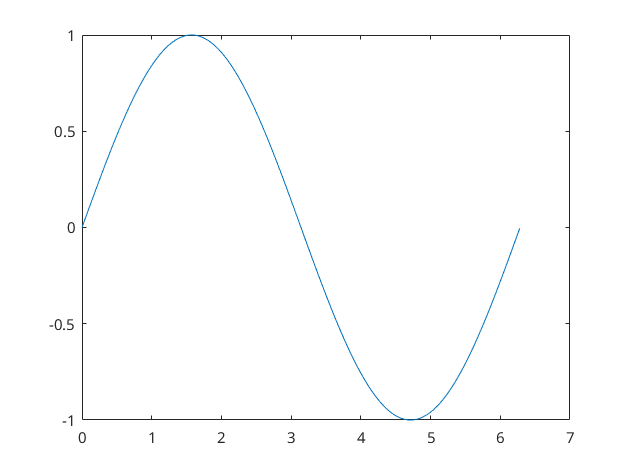

clf; % This is used to clear the previous figure
x = 0:0.01:2*pi;
y = sin(x);
z = cos(x);
xlabel 'x';
ylabel 'y';
figure(1);
plot(x,y);

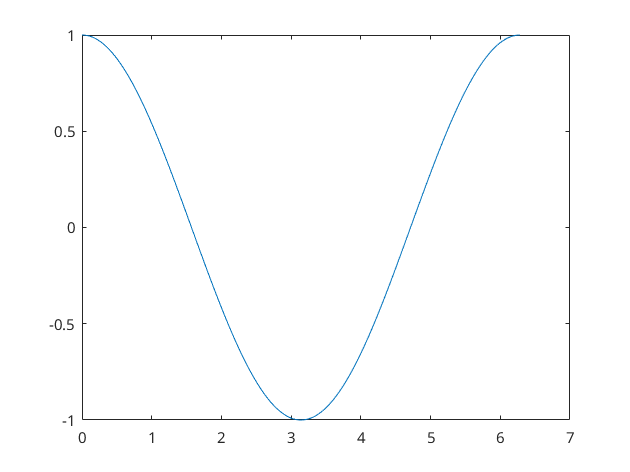

figure(2);
plot(x,z);

Note: Our axis label settings only applied to the first figure!

We can clear a figure with the `clf` command.

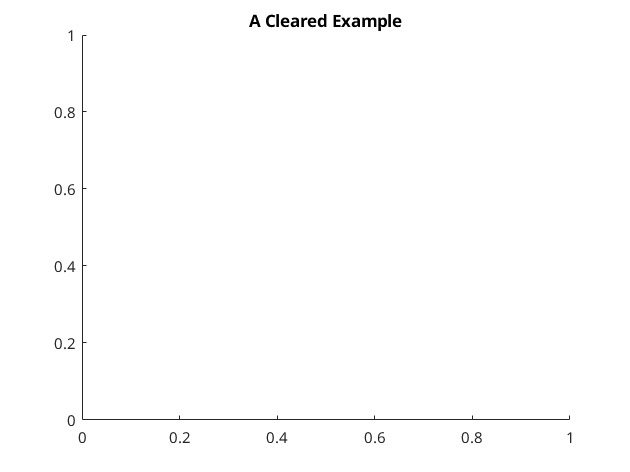

clf;
title('A Cleared Example');

## Flow Control Statements

MATLAB has two conditional flowcontrol statements (`if, switch`); two loop statements (`for, while`) and one statement for exiting a flow control region (`break`).

All of these statements, aside from block, must be closed with `end.`

### `if`

         - Evaluate if an expression is true

if 1 == 2
    disp("Something is wrong");
elseif 1 == 3
    disp("Something is definitely wrong!");
else
    disp("Everything seems okay here!");
end

Everything seems okay here!


### `switch`

         - Execute a statement based on an expression

switch 1+1
    case 1
        disp("1+1 = 1");
    case 2
        disp("1+1 = 2");
    case 3
        disp("1+1 = 3");
end

1+1 = 2


### `for`

         - Execute a block of code a set number of times.

We will pass some range that will be iterated in practice:

for i = 1:4
    fprintf("i = %i\n",i)
end

i = 1
i = 2
i = 3
i = 4


for i = [5 -2 0 3]
    fprintf("i = %i\n",i)
end

i = 5
i = -2
i = 0
i = 3


### `while`

`     - `Execute a block of code until a statement returns false

x = 0;
while x < 4
    fprintf("x = %i Keep looping!\n",x);
    x = x + 1;
end

x = 0 Keep looping!
x = 1 Keep looping!
x = 2 Keep looping!
x = 3 Keep looping!


### `break`

         - Terminate a `for` or `while` loop

a = 10;
while (a < 20)
    a = a + 1;
    if( a > 15)
        fprintf("Time to break!");
        break;
    end
    fprintf("a = %i\n",a)
end

a = 11
a = 12
a = 13
a = 14
a = 15


Time to break!

## Functions

Functions are blocks of code that execute when called. In MATLAB, functions are typically defined in separate files, with the name of the function matching the name of the file. 

If a function's file is in the matlab path, it can be called outside of the file.

An **anonymous function** is a function that we call without creating a file. We can think of these like a lambda function in C++.

They are denoted with the `@` operator.

f = @(x)(x*x);
f(2)

ans = 4

A **sub-function** is a function defined after a primary function definition in a file.

### Nested Functions

A nested function is a function defined within another (parent) function.

This allows us to share variables between the parent and nested function. When a variable is shared in this way, a local instance is created, so that two separate nested functions will not interact. Similarly, the output of a nested function is not saved to the workspace unless assigned to a variable when called ([see here for more detail](https://www.mathworks.com/help/matlab/matlab_prog/nested-functions.html)).

Consider the following example:

Here, we have `nestun` nested in the parent function, `parentfun`.

The nested function takes the value of x and creates a local instance when called. It returns a value, which here will be 6, to the variable `z`, which is saved to the workspace **only **since we assign it (**note: **y does not get saved to the workspace!)

## Efficient Programming

Avoid using nested loops whenever possible!

Consider the example: 

Compute $y_n$ for n = 1,2,3 where


$$y_n = \sum_{k=1}^{20}h_kx_{n+k}$$


clear;
% Try changing K here (by orders of magnitude) and run the methods again!
K = 20;
h = rand(K,1);
x = rand(K+3,1);
iterations = 1e5;

%Method 1 - Avoid doing this when possible!
y = zeros(1,3);
tic
for i = 1:iterations
    for n = 1:3
        for k = 1:K
            y(n) = y(n)+h(k)*x(n+k);
        end
    end
end
toc
y

% Method 2
y = zeros(1,3);

Elapsed time is 0.067990 seconds.


tic

y = 	1.0e+05 *

    4.2619    4.8229    4.4350


for i = 1:iterations
    for n = 1:3
        y(n) = h'*x((n+1):(n+K));
    end
end
toc
y

% Method 3
y = zeros(1,3);

Elapsed time is 0.080670 seconds.


X = [x(2:K+1),x(3:K+2),x(4:K+3)];

y =     4.2619    4.8229    4.4350



tic
for i = 1:iterations
    y = h'*X;
end
toc
y

## Timing

We can use `tic` and `toc` to start and stop timing.

Ex:

%help tic
%help toc
clear;

Elapsed time is 0.019357 seconds.


K = 20;

y =     4.2619    4.8229    4.4350


h = rand(K,1);
x = rand(K+3,1);

y = zeros(1,3);

% We want to loop many times to lengthen our execution time
iterations = 1e5;
tic
for n = 1:3
    for k = 1:K
        y(n) = y(n)+h(k)*x(n+k);
    end
end
toc

We can also time functions using the `timeit` command. 

By placing our function into a file, and casting it to an anonymous function, we simply call `timeit` on the anyonymous function as demonstrated below:

*Note: These methods are merely the above methods copied and pasted in a file*

%help timeit
q = @()method1(h,x,K);
r = @()method2(h,x,K);
s = @()method3(h,x,K);
t1 = timeit(q)
t2 = timeit(r)
t3 = timeit(s)

**The following is taken from the MATLAB documentation, click the link if you are interested!**

[Tips for Measuring Performance](https://de.mathworks.com/help/matlab/matlab_prog/measure-performance-of-your-program.html)

Consider the following tips when you are measuring the performance of your code:

- Time a significant enough portion of code. Ideally, the code you are timing should take more than 1/10 second to run.

- Put the code you are trying to time into a function instead of timing it at the command line or inside a script.

- Unless you are trying to measure first-time cost, run your code multiple times. Use the `timeit` function.

- Avoid `clear all` when measuring performance. For more information, see the [`clear`](https://de.mathworks.com/help/matlab/ref/clear.html) function.

- Assign your output to a variable instead of letting it default to `ans`.

## Input and Output with Files

In order to access a file in MATLAB we need to assign open it with `fopen` and assign it to a variable.

With an open file, data can be read from a file using `fscanf. `To write to a file, we can use `fprintf`.

% Writing data to file

Elapsed time is 0.002191 seconds.


output = rand(20);
file_id = fopen('writeExample.txt','w');
fprintf(file_id,'%0.4f\n',output);
fclose(file_id);

% Reading data from a file
file_id = fopen('writeExample.txt','r');
varName = fscanf(file_id,"%f")

## A Note on Accuracy

It is common to be asked to show that a result is accurate, or to be asked "how accurate is [some method]?".

Consider the following example of trying to compute $x = \frac{1}{\sqrt5}$. The specifics of the implementation do not matter here, although it will be covered later in the course.

R = 5;

t1 = 6.8313e-07

x = 1;

t2 = 1.3569e-06

t3 = 1.1477e-06

% Simple implementation of our function
newtonRecip = @(x,R)(1/2*(x+1/(R*x)));

% Loop over our iterates, using the previous x each time
for i = 1:4
    x = newtonRecip(x,R);
end
fprintf('x_%d = %.4f\n',i,x);
x - 1/sqrt(5)

Above, `x0` is the computed value that we wish to know. The deviation from the known value will give us our error.

This allows us to make the claim that "x is accurate up to 1.8363e-7".

## Extra Challenge (No marks, but good practice!)

Write a function to compute the following function for i = 1 ... n, where n is given and:


$$y_i = 1^3 * (1^3 + 2^3) * (1^3 + 2^3 + 3^3) * ... * (1^3 + 2^3 + ... + i^3)$$


(bonus: try to do this only one loop!) 

## Useful Matrix Functions

Uncomment (remove the %) to see a description on any of the following functions.

Alternatively, search the documentation in the top-right!

%help zeros
zeros(3)
%help ones
ones(3)
%help eye
eye(3)
%help rand
rand()
rand(3)

varName =     0.7802
    0.3376
    0.6079
    0.7413
    0.1048
    0.1279
    0.5495
    0.4852
    0.8905
    0.7990


%help diag
M = diag([1,2,3])
diag(M)
%help size
size(M)
colV = [1;2;3];
size(colV)
%help length
length(colV)
%help det
det(M)
%help inv
inv(M)
%help eig
[V,D] = eig(M)

x_4 = 0.4472


%help rank

ans =    1.8363e-07


rank(M)
clear();

## Math Functions

Uncomment (remove the %) to see a description on any of the following functions.

Alternatively, search the documentation in the top-right!

%help abs
M = -ones(3);

ans =      0     0     0
     0     0     0
     0     0     0


abs(M)
%help sin

ans =      1     1     1
     1     1     1
     1     1     1


sin(M)
%help sinh

ans =      1     0     0
     0     1     0
     0     0     1


sinh(M)
%help asin

ans = 0.5906

asin(M)

ans =     0.6604    0.4513    0.8562
    0.0476    0.2409    0.2815
    0.3488    0.7150    0.7311


%help asinh
asinh(M)

M =      1     0     0
     0     2     0
     0     0     3


%help exp

ans =      1
     2
     3


M = [1,2;3,4];
exp(M)

ans =      3     3


%help log
log(M)

ans =      3     1


%help log10
log10(M)

ans = 3

%help sort
N = [2.3,1.7;-1.2,4.3];

ans = 6

v = [2.3,1.7,-1.2,4.3];
sort(N)

ans =     1.0000         0         0
         0    0.5000         0
         0         0    0.3333


sort(v)
%help round

V =      1     0     0
     0     1     0
     0     0     1


D =      1     0     0
     0     2     0
     0     0     3


round(N)
%help max

ans = 3

max(N)
%help min
min(N)
%help mean
mean(N)
%help median
median(N)
%help real

ans =      1     1     1
     1     1     1
     1     1     1


x = 1 + 2i;
real(x)

ans =    -0.8415   -0.8415   -0.8415
   -0.8415   -0.8415   -0.8415
   -0.8415   -0.8415   -0.8415


%help imag
imag(x)

ans =    -1.1752   -1.1752   -1.1752
   -1.1752   -1.1752   -1.1752
   -1.1752   -1.1752   -1.1752


clear();

ans =    -1.5708   -1.5708   -1.5708
   -1.5708   -1.5708   -1.5708
   -1.5708   -1.5708   -1.5708


ans =    -0.8814   -0.8814   -0.8814
   -0.8814   -0.8814   -0.8814
   -0.8814   -0.8814   -0.8814


ans =     2.7183    7.3891
   20.0855   54.5982


ans =          0    0.6931
    1.0986    1.3863


ans =          0    0.3010
    0.4771    0.6021


ans =    -1.2000    1.7000
    2.3000    4.3000


ans =    -1.2000    1.7000    2.3000    4.3000


ans =      2     2
    -1     4


ans =     2.3000    4.3000


ans =    -1.2000    1.7000


ans = 1×2
    0.5500    3.0000


ans = 1×2
    0.5500    3.0000


ans = 1

ans = 2